# Star Detection Testing

I = (imread('data/calibrated_raw/20250321T192420_651_StackInput.tiff'));
I2 = (imread('data/calibrated_raw/20250321T192416_651_StackInput.tiff'));
addpath('code');

Centroid

t1 = tic;
% reduce noise
I_thresh = .1 * 65535;
I_cutoff = gray;
I_cutoff(I_cutoff < I_thresh) = 0;
I_smooth = imgaussfilt(I_cutoff, 1);
bwMax = imregionalmax(I_smooth);


% get centroids
stats = regionprops(bwMax, gray, 'WeightedCentroid');

% convert to arrays
star_points = cat(1, stats.WeightedCentroid);

% get brightness
% extract x/y
x = round(star_points(:,1));
y = round(star_points(:,2));

% clamp to valid indices
x = min(max(x,1), size(I,2));
y = min(max(y,1), size(I,1));

% get brightness
brightness = I(sub2ind(size(I), y, x));

% sort by brightness
[~, order] = sort(brightness, 'descend');

% keep top N brightest
N = 10;
idx_keep = order(1:min(N,end));
star_points = star_points(idx_keep, :);
brightness  = brightness(idx_keep);  % truncate brightness to match points

% remove duplicates
min_dist = 20;
star_points = remove_duplicate_points(star_points, brightness, min_dist);
fprintf('t: %.2f s\n', toc(t1));

t: 0.08 s


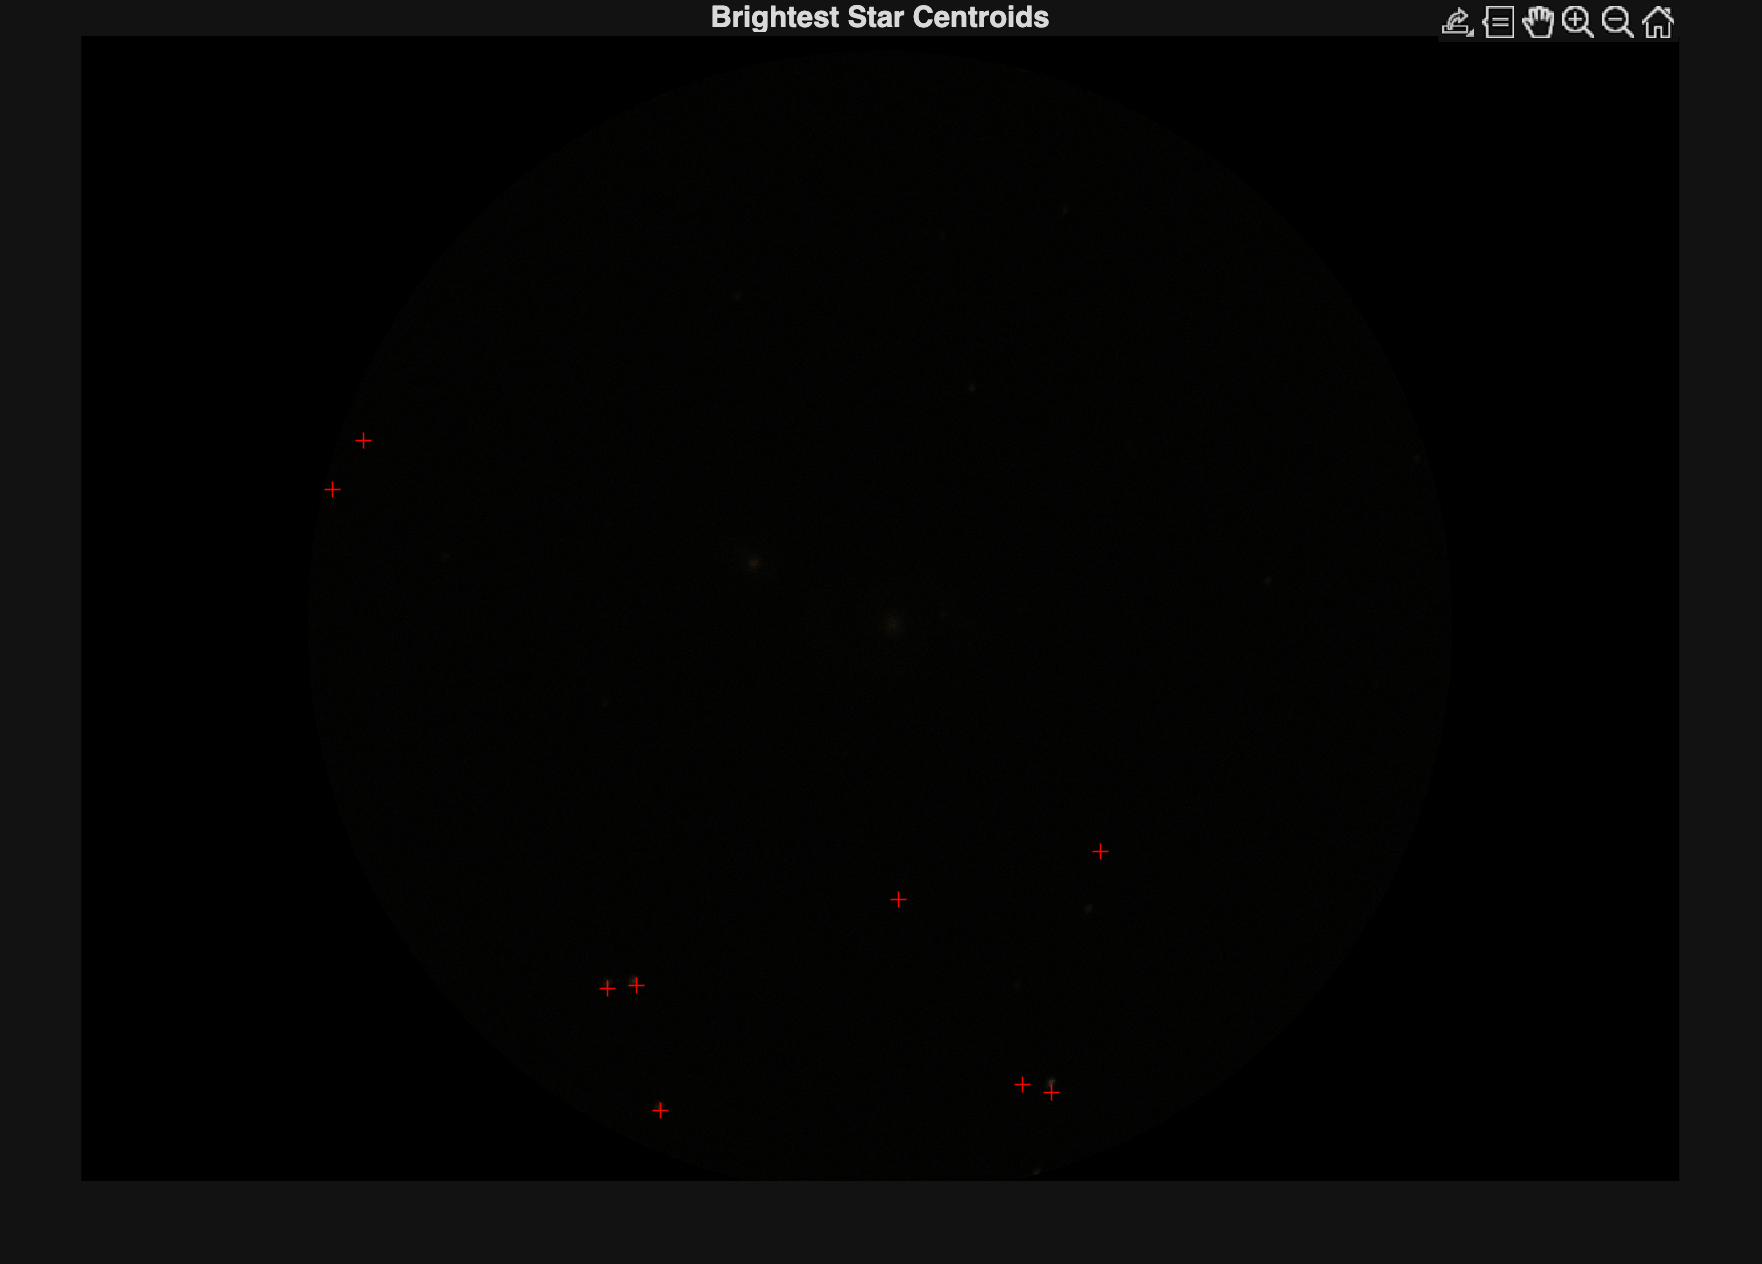


% plot
imshow(I, []); hold on;
plot(star_points(:,1), star_points(:,2), 'r+');
title('Brightest Star Centroids');

Local Maxima

points = get_star_tracking_points(I);


imshow(I, []); hold on;
if true
    plot(points(:,1), points(:,2), 'r+');
    title('Stars above brightness threshold');
end

Detect Dark

dark = imread('data/darkframe.tiff');
dark_points = get_star_tracking_points(dark);


imshow(dark, []); hold on;
if true
    plot(dark_points(:,1), dark_points(:,2), 'r+');
    title('Darkframe');
end

Overlay 

imshow(I, []); hold on;
if true
    plot(points(:,1), points(:,2), 'r+');
    plot(dark_points(:,1), dark_points(:,2), 'go');
    title('Stars with overlay of dark plot');
end

Remove Dark Overlay

dark = imread('data/darkframe.tiff');
points = get_star_tracking_points(I-dark);


imshow(I-dark, []); hold on;
if true
    plot(points(:,1), points(:,2), 'r+');
    plot(dark_points(:,1), dark_points(:,2), 'go');
    title('Stars - Dark');
end